## Square Wave Tutorial

The square wave is a special type of waveform often encountered in electronics and signal processing.  In music, the square wave is one of several basic oscillators used in subtractive synthesis.

The square wave is also an excellent example that can be used to show the concept of Fourier decomposition.  A square wave is made up of the sum of multiple amplitude-scaled harmonics of a fundamental sinusoid.

This Live Script document will walk you through how a square wave is constructed from the sum of multiple sine waves.

## Build your own square wave

While the Fourier series equation shows the square wave is the sum of infinitely many odd-integer harmonic sinusoids, we obviously can't do that as a simulation.  However, we can demonstrate how the square wave starts to take form as more and more odd harmonics are added.  Use the sliders to construct your Fourier seriers representation of a square wave.  Observe how the square wave starts to take shape as you add more and more harmonics.  Also notice how the overshoot artifacts at the edges of the square wave transitions.

Explore further by viewing the Fourier (Frequency) domain representation of the square wave you created.

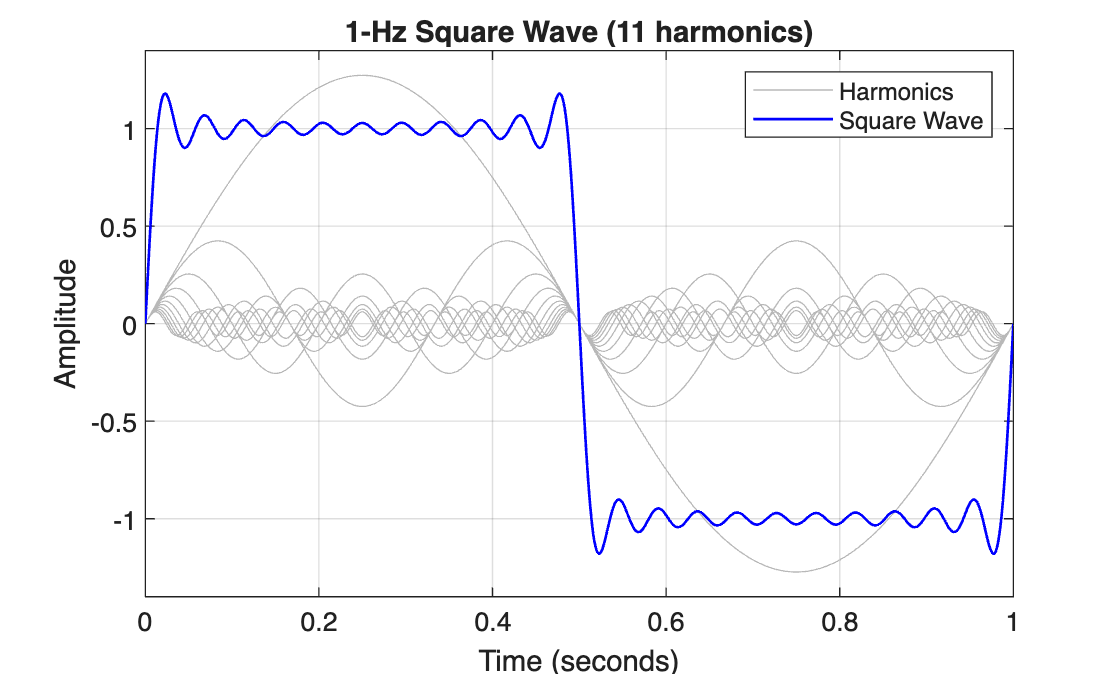

f = 1; % square wave fundamental frequency (Hz)
K = 11; % number of odd harmonics

fs = 1000; % sampling frequency (samples/second)
dur = 1; % square wave duration (seconds)
t = (0:1/fs:dur)'; % time vector (seconds)
fr = fs*(0:numel(t)-1)'/numel(t);

yt = [];
for k = 1:K
    yt(:,k) = (4/pi)*(1/(2*k-1))*sin(2*pi*(2*k-1)*f*t);
end

f2 = figure;
ax2 = axes;

domain = "Time Domain";  

if domain == 'Time Domain'
    plot(ax2,t,yt,'Color',0.72*ones(1,3),'LineWidth',0.5);
    hold on;
    plot(ax2,t,sum(yt,2),'b-','LineWidth',1);
    xlabel('Time (seconds)');
    ylabel('Amplitude');
    ylim([-1.4 1.4]);
    grid on;
    legend(ax2.Children([end 1]),{'Harmonics','Square Wave'});
    title(ax2,sprintf('%d-Hz Square Wave (%d harmonics)',f,K));
    hold off;
elseif domain == 'Frequency Domain'
    Yw = fft(sum(yt,2));
    stem(ax2,fr,abs(Yw)/numel(Yw),'r.-');
    xlabel('Frquency (Hz)');
    ylabel('Magnitude');
    grid on;
    xlim([0 f*(2*(K+1)-1)]);
    title(ax2,sprintf('%d-Hz Square Wave (%d harmonics)',f,K));
    hold off;
end